close all; clear; clc;

# P80 50-90% throttle ramp up

**file name**: STv2_1_1_3bat_MEGA30d3b_20181204_1.mlx

**keywords:** 

**date of test:** date

**file created by:** date, Edmonds

**last updated on:** YYYYMMDD

**primary purpose:** 

**primary input and output variables: **

calculated/not measured from test stand- motor radius and rho. 

measured from test stand- time, ESC us, Torque, Thrust, input voltage, input current, rotational speed (omega), input power, output power, efficiencies (motor, prop, overall), temp probe (by motor)

**functions:** 

**Notes:** 

## Input Variables

Use Atmospheric Condition Calculator to calculate air density

% Air Density
p = 0.002377;                  %SLS [slugs/ft^3]

% Motor Specs
diameter = 27 / 12 ;
radius = diameter/2;               % [ft]
area = pi * radius^(2);       % [ft^2]

## Measured Data 1 

This format assumes that the data output from RC Benchmark has not been changed

load('STv2_1_1_3bat_MEGA30d3b_20181204_1.mat');
time1 = STv2_1_1_3bat_MEGA30d3b_20181204_1(:,1);                       % [sec]
PWM1 = STv2_1_1_3bat_MEGA30d3b_20181204_1(:,2);                        % [micro sec]
Q1 = STv2_1_1_3bat_MEGA30d3b_20181204_1(:,4);                          % [ft.lbf]
T1 = STv2_1_1_3bat_MEGA30d3b_20181204_1(:,5);                          % [lbf]
Input_V1 = STv2_1_1_3bat_MEGA30d3b_20181204_1(:,6);                    % [Volts]
Input_A1 = STv2_1_1_3bat_MEGA30d3b_20181204_1(:,7);                    % [Amps]
rot_speed_rpm1 = STv2_1_1_3bat_MEGA30d3b_20181204_1(:,8);              % [RPM]
% convert to RPM for plotting purposes
rot_speed_rad1 = rot_speed_rpm1 .* (pi/30);   % [rad/sec]
P_in_W1 = STv2_1_1_3bat_MEGA30d3b_20181204_1(:,9);                     % [Watts]
P_out_W1 = STv2_1_1_3bat_MEGA30d3b_20181204_1(:,10);                   % [Watts]
% convert to [ft.lbf/sec]
P_out1 = P_out_W1 .* 0.7478;                  % [ft.lbf/sec]         
P_in1 = P_in_W1 .* 0.7478;                    % [ft.lbf/sec]
Motor_Eff1 = STv2_1_1_3bat_MEGA30d3b_20181204_1(:,11);                 % [%]
Prop_Eff1 = STv2_1_1_3bat_MEGA30d3b_20181204_1(:,12);                  % [lbf/Watts]
Overall_Eff1 = STv2_1_1_3bat_MEGA30d3b_20181204_1(:,13);               % [lbf/Watts]  
ESC_Temp1 = STv2_1_1_3bat_MEGA30d3b_20181204_1(:,14);                  % [F]
Motor_Temp1 = STv2_1_1_3bat_MEGA30d3b_20181204_1(:,15);                % [F]

disk_loading1 = T1 ./ area;                     % [lb/sq.ft]

throttle1 = (PWM1 - 1000) ./ 10;

Settling_time1 = STv2_1_1_3bat_MEGA30d3b_20181204_1(:,17); % [s]
Max_Acc1 = STv2_1_1_3bat_MEGA30d3b_20181204_1(:,18);      % [RPM]

C_T1 = T1 ./ (p .* area * (rot_speed_rad1 * radius).^2);
C_P1 = P_out1 ./ (p .* area .* (rot_speed_rad1 .* radius).^3);
C_Q1 = Q1 ./ (p .* area .* (rot_speed_rad1 .* radius).^(2) .* radius);

## Measured Data 2

This format assumes that the data output from RC Benchmark has not been changed

load('STv2_1_1_3bat_MEGA30d3b_20181204_2.mat');
time2 = STv2_1_1_3bat_MEGA30d3b_20181204_2(:,1);                       % [sec]
PWM2 = STv2_1_1_3bat_MEGA30d3b_20181204_2(:,2);                        % [micro sec]
Q2 = STv2_1_1_3bat_MEGA30d3b_20181204_2(:,4);                          % [ft.lbf]
T2 = STv2_1_1_3bat_MEGA30d3b_20181204_2(:,5);                          % [lbf]
Input_V2 = STv2_1_1_3bat_MEGA30d3b_20181204_2(:,6);                    % [Volts]
Input_A2 = STv2_1_1_3bat_MEGA30d3b_20181204_2(:,7);                    % [Amps]
rot_speed_rpm2 = STv2_1_1_3bat_MEGA30d3b_20181204_2(:,8);              % [RPM]
% convert to RPM for plotting purposes
rot_speed_rad2 = rot_speed_rpm2 .* (pi/30);   % [rad/sec]
P_in_W2 = STv2_1_1_3bat_MEGA30d3b_20181204_2(:,9);                     % [Watts]
P_out_W2 = STv2_1_1_3bat_MEGA30d3b_20181204_2(:,10);                   % [Watts]
% convert to [ft.lbf/sec]
P_out2 = P_out_W2 .* 0.7478;                  % [ft.lbf/sec]         
P_in2 = P_in_W2 .* 0.7478;                    % [ft.lbf/sec]
Motor_Eff2 = STv2_1_1_3bat_MEGA30d3b_20181204_2(:,11);                 % [%]
Prop_Eff2 = STv2_1_1_3bat_MEGA30d3b_20181204_2(:,12);                  % [lbf/Watts]
Overall_Eff2 = STv2_1_1_3bat_MEGA30d3b_20181204_2(:,13);               % [lbf/Watts]  
ESC_Temp2 = STv2_1_1_3bat_MEGA30d3b_20181204_2(:,14);                  % [F]
Motor_Temp2 = STv2_1_1_3bat_MEGA30d3b_20181204_2(:,15);                % [F]

disk_loading2 = T2 ./ area;                     % [lb/sq.ft]

throttle2 = (PWM2 - 1000) ./ 10;

Settling_time2 = STv2_1_1_3bat_MEGA30d3b_20181204_2(:,17); % [s]
Max_Acc2 = STv2_1_1_3bat_MEGA30d3b_20181204_2(:,18);      % [RPM]

C_T2 = T2 ./ (p .* area * (rot_speed_rad2 * radius).^2);
C_P2 = P_out2 ./ (p .* area .* (rot_speed_rad2 .* radius).^3);
C_Q2 = Q2 ./ (p .* area .* (rot_speed_rad2 .* radius).^(2) .* radius);


## Measured Data 3

This format assumes that the data output from RC Benchmark has not been changed

load('STv2_1_1_3bat_MEGA30d3b_20181204_3.mat');
time3 = STv2_1_1_3bat_MEGA30d3b_20181204_3(:,1);                       % [sec]
PWM3 = STv2_1_1_3bat_MEGA30d3b_20181204_3(:,2);                        % [micro sec]
Q3 = STv2_1_1_3bat_MEGA30d3b_20181204_3(:,4);                          % [ft.lbf]
T3 = STv2_1_1_3bat_MEGA30d3b_20181204_3(:,5);                          % [lbf]
Input_V3 = STv2_1_1_3bat_MEGA30d3b_20181204_3(:,6);                    % [Volts]
Input_A3 = STv2_1_1_3bat_MEGA30d3b_20181204_3(:,7);                    % [Amps]
rot_speed_rpm3 = STv2_1_1_3bat_MEGA30d3b_20181204_3(:,8);              % [RPM]
% convert to RPM for plotting purposes
rot_speed_rad3 = rot_speed_rpm3 .* (pi/30);   % [rad/sec]
P_in_W3 = STv2_1_1_3bat_MEGA30d3b_20181204_3(:,9);                     % [Watts]
P_out_W3 = STv2_1_1_3bat_MEGA30d3b_20181204_3(:,10);                   % [Watts]
% convert to [ft.lbf/sec]
P_out3 = P_out_W3 .* 0.7478;                  % [ft.lbf/sec]         
P_in3 = P_in_W3 .* 0.7478;                    % [ft.lbf/sec]
Motor_Eff3 = STv2_1_1_3bat_MEGA30d3b_20181204_3(:,11);                 % [%]
Prop_Eff3 = STv2_1_1_3bat_MEGA30d3b_20181204_3(:,12);                  % [lbf/Watts]
Overall_Eff3 = STv2_1_1_3bat_MEGA30d3b_20181204_3(:,13);               % [lbf/Watts]  
ESC_Temp3 = STv2_1_1_3bat_MEGA30d3b_20181204_3(:,14);                  % [F]
Motor_Temp3 = STv2_1_1_3bat_MEGA30d3b_20181204_3(:,15);                % [F]

disk_loading3 = T3 ./ area;                     % [lb/sq.ft]

throttle3 = (PWM3 - 1000) ./ 10;

Settling_time3 = STv2_1_1_3bat_MEGA30d3b_20181204_3(:,17); % [s]
Max_Acc3 = STv2_1_1_3bat_MEGA30d3b_20181204_3(:,18);      % [RPM]

C_T3 = T3 ./ (p .* area * (rot_speed_rad3 * radius).^2);
C_P3 = P_out3 ./ (p .* area .* (rot_speed_rad3 .* radius).^3);
C_Q3 = Q3 ./ (p .* area .* (rot_speed_rad3 .* radius).^(2) .* radius);





## Plots

The following are standard charts. Remove, add, and edit as needed.

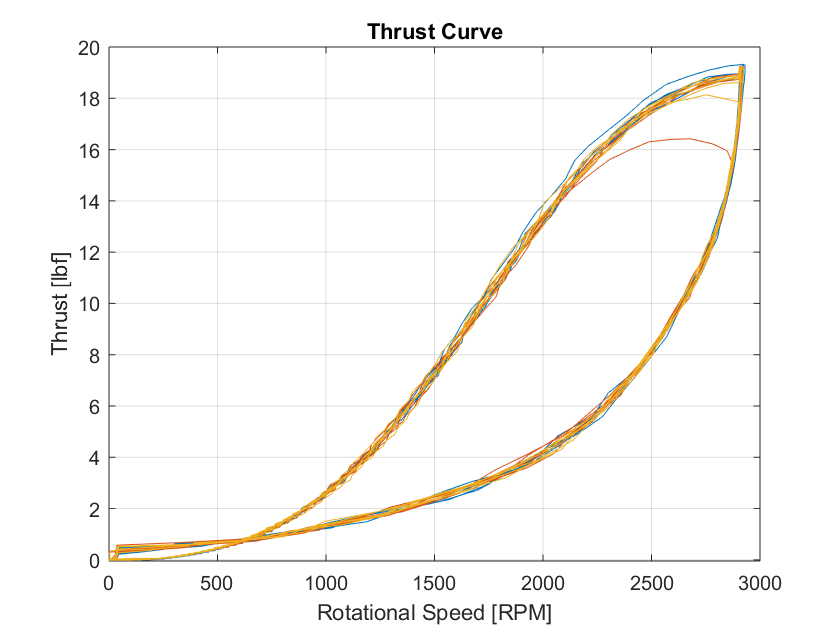

figure(1)
plot(rot_speed_rpm1, T1, rot_speed_rpm2, T2, rot_speed_rpm3, T3); 
title('Thrust Curve'); 
xlabel('Rotational Speed [RPM]'); ylabel('Thrust [lbf]'); grid('on');

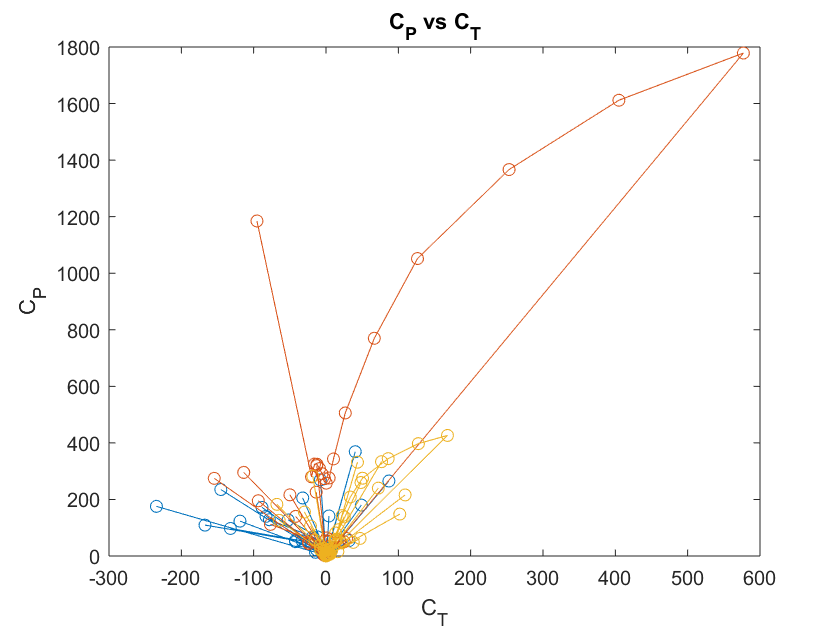


figure(2)
plot(C_T1, C_P1,'o-', C_T2, C_P2,'o-', C_T3, C_P3,'o-');
title('C_P vs C_T'); xlabel('C_T'); ylabel('C_P')

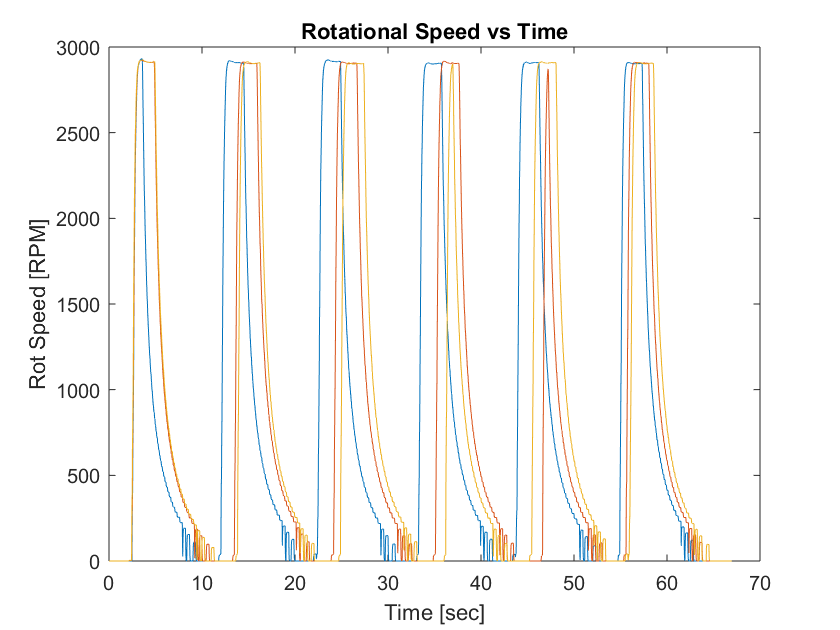


figure(3)
plot(time1, rot_speed_rpm1, time2, rot_speed_rpm2, time3, rot_speed_rpm3); 
title('Rotational Speed vs Time'); 
xlabel('Time [sec]'); ylabel('Rot Speed [RPM]')

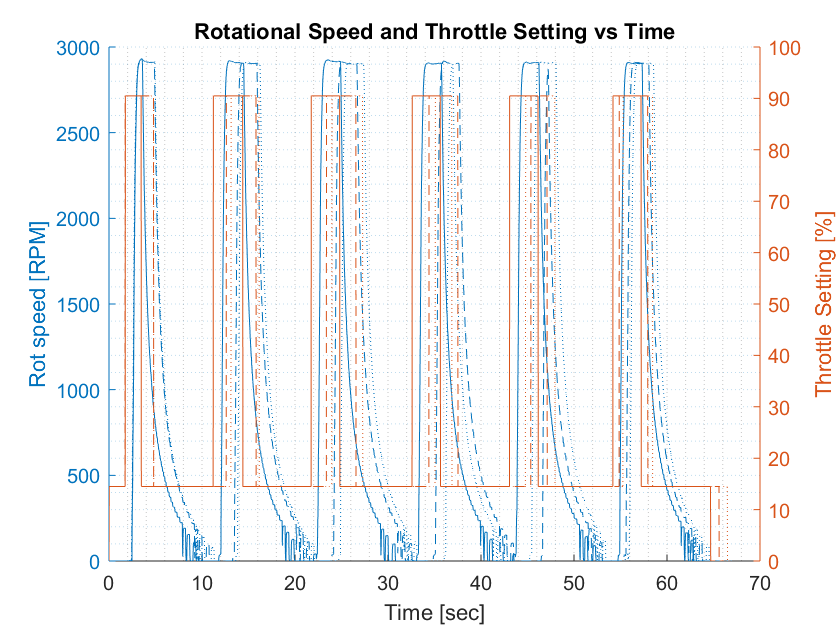


figure(4)
hold on
yyaxis left
plot(time1, rot_speed_rpm1, time2, rot_speed_rpm2, time3, rot_speed_rpm3);
ylabel('Rot speed [RPM]');
yyaxis right
plot(time1, throttle1, time2, throttle2, time3, throttle3);
ylabel('Throttle Setting [%]');
title('Rotational Speed and Throttle Setting vs Time');
xlabel('Time [sec]');
grid('minor');
hold off

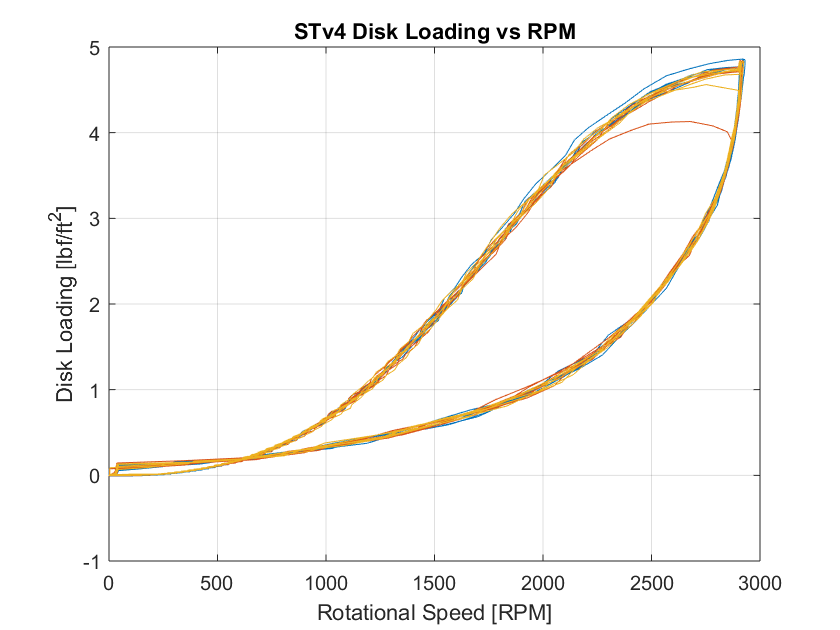


figure(5)
plot(rot_speed_rpm1, disk_loading1, rot_speed_rpm2, disk_loading2, rot_speed_rpm3, disk_loading3); 
title('STv4 Disk Loading vs RPM');
xlabel('Rotational Speed [RPM]'); ylabel('Disk Loading [lbf/ft^2]')
grid('on');

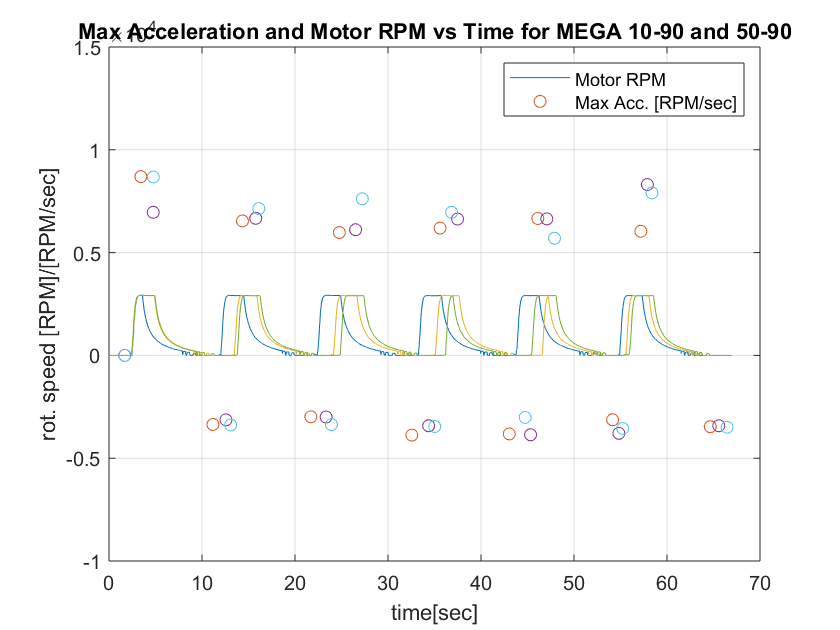


figure(6)
plot(time1, rot_speed_rpm1, time1, Max_Acc1, 'o', time2, rot_speed_rpm2, time2, Max_Acc2, 'o', time3, rot_speed_rpm3, time3, Max_Acc3, 'o');
title('Max Acceleration and Motor RPM vs Time for MEGA 10-90 and 50-90');
xlabel('time[sec]'); ylabel('rot. speed [RPM]/[RPM/sec]'); 
legend('Motor RPM', 'Max Acc. [RPM/sec]'); grid('on');
ylim([-1E4 1.5E4]);

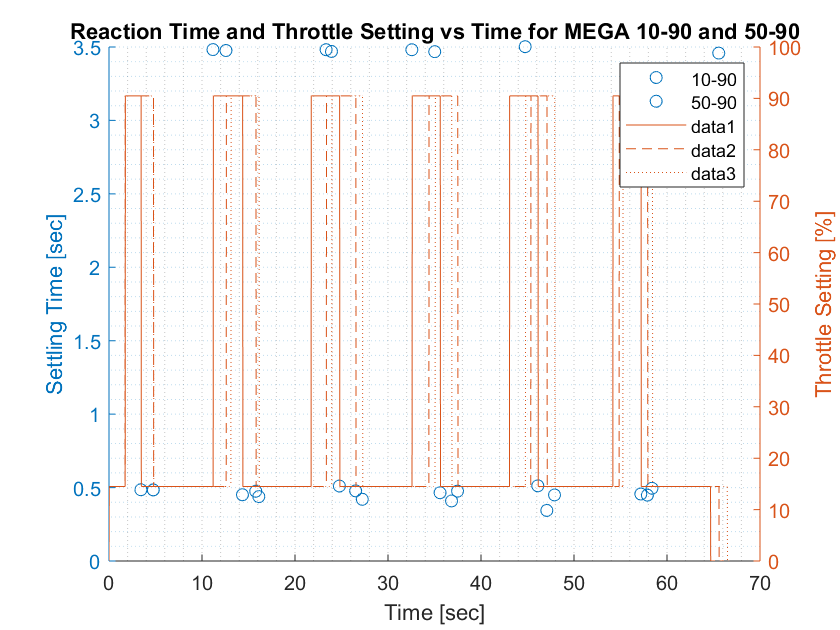


figure(7)
hold on
yyaxis left
plot(time1, Settling_time1, 'o', time2,Settling_time2, 'o', time3,Settling_time3, 'o');
legend('10-90', '50-90');
ylim([0 3.5]);
ylabel('Settling Time [sec]');
yyaxis right
plot(time1, throttle1, time2, throttle2, time3, throttle3);
ylabel('Throttle Setting [%]');
title('Reaction Time and Throttle Setting vs Time for MEGA 10-90 and 50-90');
xlabel('Time [sec]');
grid('minor');
hold off

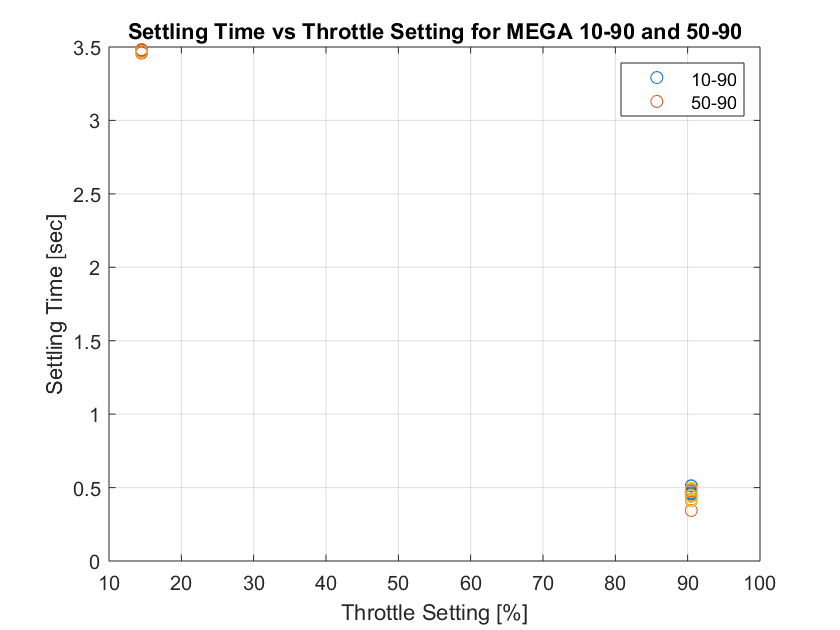


figure(8)
plot(throttle1, Settling_time1, 'o', throttle2, Settling_time2, 'o', throttle3, Settling_time3, 'o');
title('Settling Time vs Throttle Setting for MEGA 10-90 and 50-90'); xlabel('Throttle Setting [%]');
ylabel('Settling Time [sec]');
ylim([0 3.5]);
legend('10-90', '50-90'); grid('on');

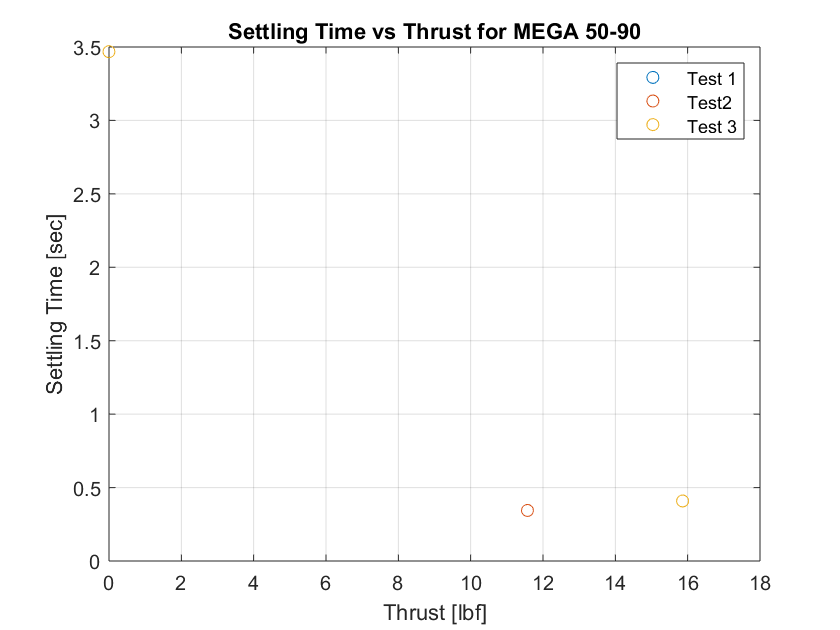


figure(9)
plot(T1, Settling_time1, 'o', T2, Settling_time2, 'o', T3, Settling_time3, 'o');
title('Settling Time vs Thrust for MEGA 50-90'); 
xlabel('Thrust [lbf]');
ylabel('Settling Time [sec]');
ylim([0 3.5]);
xlim([0 18]);
legend('Test 1', 'Test2', 'Test 3'); grid('on');

## Comparing Data to Momentum Theory

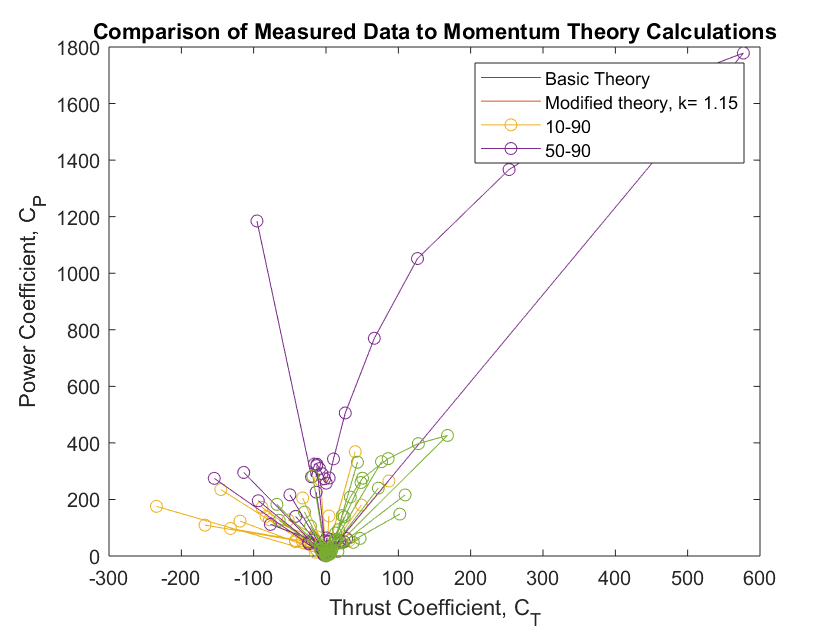

k = 1.15;
C_T_theory = linspace(0, 0.015, 1000);
C_P_theory = C_T_theory .^(3/2) ./ sqrt(2);
C_Pi = k .* (C_T_theory .^(3/2) ./ sqrt(2));

figure(100)
plot(C_T_theory, C_P_theory, C_T_theory, C_Pi, C_T1, C_P1, 'o-', C_T2, C_P2, 'o-', C_T3, C_P3, 'o-');
title('Comparison of Measured Data to Momentum Theory Calculations');
xlabel('Thrust Coefficient, C_T'); ylabel('Power Coefficient, C_P');
legend('Basic Theory', 'Modified theory, k= 1.15', '10-90', '50-90');